# Presentación Final (Cinemática Diferencial de Piernas)

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;                      %Matriz identidad
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(roty(0), [1.3 0 0]);
H3=SE3(rotx(0), [1.5 0 0]);
H4=SE3(rotx(0), [1.7 0 0]);

H0_1= H0*H1;
H1_2= H0_1*H2;
H2_3= H1_2*H3; %Matriz de transformación homogenea global de 3 a 0 }
H3_4= H2_3*H4; 

%Coordenadas de la estructura de translación y rotación
x=[4.5 0 0 0 0 0 0 0 0 0];
y=[0 0 0 0 0 0 0 0 0 0];
z=[2 2 0 0 0 0 0 0 0 0]; 

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H0_1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0_1, H1_2,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H1_2, H2_3,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H2_3)

    1         0         0       2.8
    0         0        -1         0
    0         1         0         2
    0         0         0         1


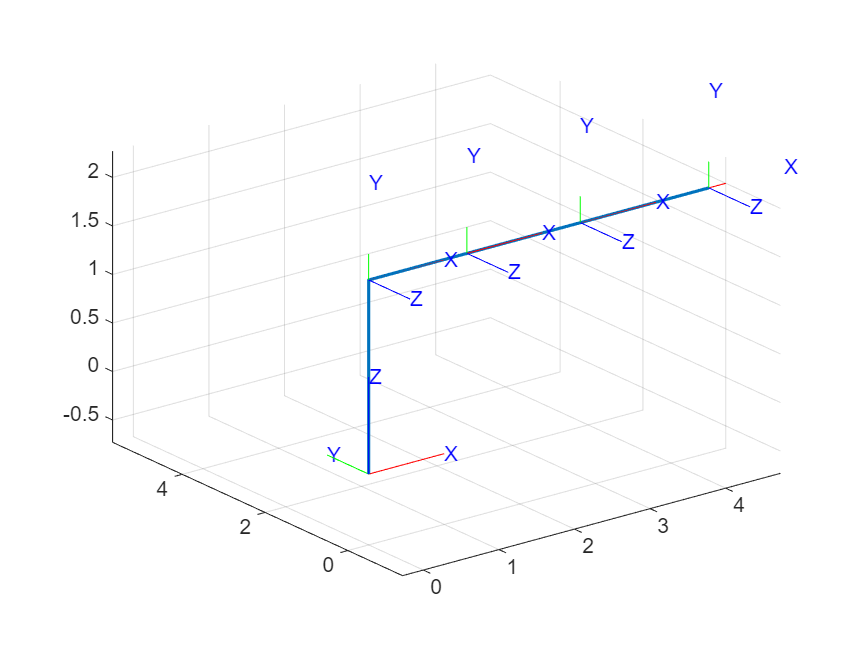


   pause;           
  tranimate(H2_3, H3_4,'rgb','axis', [-1 4 -1 6 -1 2])

  disp(H3_4)

    1         0         0       4.5
    0         0        -1         0
    0         1         0         2
    0         0         0         1


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Codigo para calcular velocidades lineales y angulares


% Variables simbólicas para traslaciones (pueden ser funciones de t si quieres)
syms l1(t) l2(t) l3(t) l4(t) t real


% Si quisieras también ángulos variables, se pueden agregar.
% Aquí las rotaciones son fijas (pi/2 o 0), pero las traslaciones variables.

% Vector de variables generalizadas (traslaciones)
Q = [l1; l2; l3; l4];
Qp = diff(Q, t);  % Velocidades generalizadas

% Tipo de juntas: todas prismáticas (traslaciones)
RP = [1 1 1 1];

% Funciones para rotaciones alrededor de X y Y
Rx = @(theta) [1 0 0; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
Ry = @(theta) [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];

% Definir matrices homogéneas locales A(:,:,i) con rotación fija y traslación variable

A(:,:,1) = [Rx(pi/2)     [0; 0; l1(t)]; 0 0 0 1];
A(:,:,2) = [Ry(0)       [l2(t); 0; 0]; 0 0 0 1];
A(:,:,3) = [Rx(0)       [l3(t); 0; 0]; 0 0 0 1];
A(:,:,4) = [Rx(0)       [l4(t); 0; 0]; 0 0 0 1];

Vector_Zeros = [0 0 0];
GDL = length(RP);

% Inicializamos las transformaciones globales simbólicas
T(:,:,1) = simplify(A(:,:,1));

for i = 2:GDL
    T(:,:,i) = simplify(T(:,:,i-1)*A(:,:,i));
end

% Extraer posiciones y rotaciones globales
for i = 1:GDL
    PO(:,i) = T(1:3,4,i);
    RO(:,:,i) = T(1:3,1:3,i);
end

% Jacobiano analítico (lineal y angular)
Jv = sym(zeros(3,GDL));
Jw = sym(zeros(3,GDL));

for k = 1:GDL
    if RP(k) == 0  % Junta rotacional
        if k == 1
            z_prev = [0; 0; 1];
            p_prev = [0; 0; 0];
        else
            z_prev = RO(:,3,k-1);
            p_prev = PO(:,k-1);
        end
        Jv(:,k) = cross(z_prev, PO(:,GDL) - p_prev);
        Jw(:,k) = z_prev;
    else           % Junta prismática
        if k == 1
            z_prev = [0; 0; 1];
        else
            z_prev = RO(:,3,k-1);
        end
        Jv(:,k) = z_prev;
        Jw(:,k) = [0; 0; 0];
    end
end

Jv = simplify(Jv);
Jw = simplify(Jw);

% Velocidades lineales y angulares simbólicas
V = simplify(Jv * Qp);
W = simplify(Jw * Qp);

% Mostrar resultados
for i = 1:GDL
    fprintf('Matriz global T%d:\n', i);
    pretty(T(:,:,i));
end

Matriz global T1:


/ 1,                 0,                                0,                  0   \
|                                                                              |
|            4967757600021511                                                  |
| 0, --------------------------------,                -1,                  0   |
|    81129638414606681695789005144064                                          |
|                                                                              |
|                                              4967757600021511                |
| 0,                 1,                --------------------------------, l1(t) |
|                                      81129638414606681695789005144064        |
|                                                                              |
\ 0,                 0,                                0,                  1   /



Matriz global T2:


/ 1,                 0,                                0,                l2(t) \
|                                                                              |
|            4967757600021511                                                  |
| 0, --------------------------------,                -1,                  0   |
|    81129638414606681695789005144064                                          |
|                                                                              |
|                                              4967757600021511                |
| 0,                 1,                --------------------------------, l1(t) |
|                                      81129638414606681695789005144064        |
|                                                                              |
\ 0,                 0,                                0,                  1   /



Matriz global T3:


/ 1,                 0,                                0,                l2(t) + l3(t) \
|                                                                                      |
|            4967757600021511                                                          |
| 0, --------------------------------,                -1,                      0       |
|    81129638414606681695789005144064                                                  |
|                                                                                      |
|                                              4967757600021511                        |
| 0,                 1,                --------------------------------,     l1(t)     |
|                                      81129638414606681695789005144064                |
|                                                                                      |
\ 0,                 0,                                0,                      1       /



Matriz global T4:


/ 1,                 0,                                0,                l2(t) + l3(t) + l4(t) \
|                                                                                              |
|            4967757600021511                                                                  |
| 0, --------------------------------,                -1,                          0           |
|    81129638414606681695789005144064                                                          |
|                                                                                              |
|                                              4967757600021511                                |
| 0,                 1,                --------------------------------,         l1(t)         |
|                                      81129638414606681695789005144064                        |
|                                                                                              |
\ 0,                 0,       


disp('Jacobiano lineal analítico:');

Jacobiano lineal analítico:


pretty(Jv);

/ 0,                 0,                                0,                                0                \
|                                                                                                         |
| 0,                -1,                               -1,                               -1                |
|                                                                                                         |
|            4967757600021511                  4967757600021511                  4967757600021511         |
| 1, --------------------------------, --------------------------------, -------------------------------- |
\    81129638414606681695789005144064  81129638414606681695789005144064  81129638414606681695789005144064 /



disp('Jacobiano angular analítico:');

Jacobiano angular analítico:


pretty(Jw);

/ 0, 0, 0, 0 \
|            |
| 0, 0, 0, 0 |
|            |
\ 0, 0, 0, 0 /




disp('Velocidad lineal simbólica V:');

Velocidad lineal simbólica V:


pretty(V);

/                                                         0                                                         \
|                                                                                                                   |
|                                             d          d          d                                               |
|                                          - -- l2(t) - -- l3(t) - -- l4(t)                                         |
|                                            dt         dt         dt                                               |
|                                                                                                                   |
|                                  d                                  d                                  d          |
|                4967757600021511 -- l2(t)          4967757600021511 -- l3(t)          4967757600021511 -- l4(t)    |
|  d                              dt                    

disp('Velocidad angular simbólica W:');

Velocidad angular simbólica W:


pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



clear
cla 
clf

%Calculamos las matrices de transformación homogénea
H0=SE3(roty(pi/2), [0 0 0]);                 %Matriz identidad
H1=SE3(rotx(pi/2), [0 0 0]);
H2=SE3(rotx(pi/2), [0 0 0]);
H3=SE3(rotx(-pi/2), [1.5 0 0]);
H4=SE3(rotx(0), [2 0 0]);

H0_1= H0*H1;
H1_2= H0_1*H2;
H2_3= H1_2*H3; %Matriz de transformación homogenea global de 3 a 0 }
H3_4= H2_3*H4; 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1.5 0 0 0 0 0 0 0];
y=[0 0 0 0 0 0 0 0 0 0];
z=[-4 0 0 0 0 0 0 0 0 0];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -5 1]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H0_1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0_1, H1_2,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H1_2, H2_3,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H2_3)

     0         1         0         0
     0         0        -1         0
    -1         0         0      -1.5
     0         0         0         1


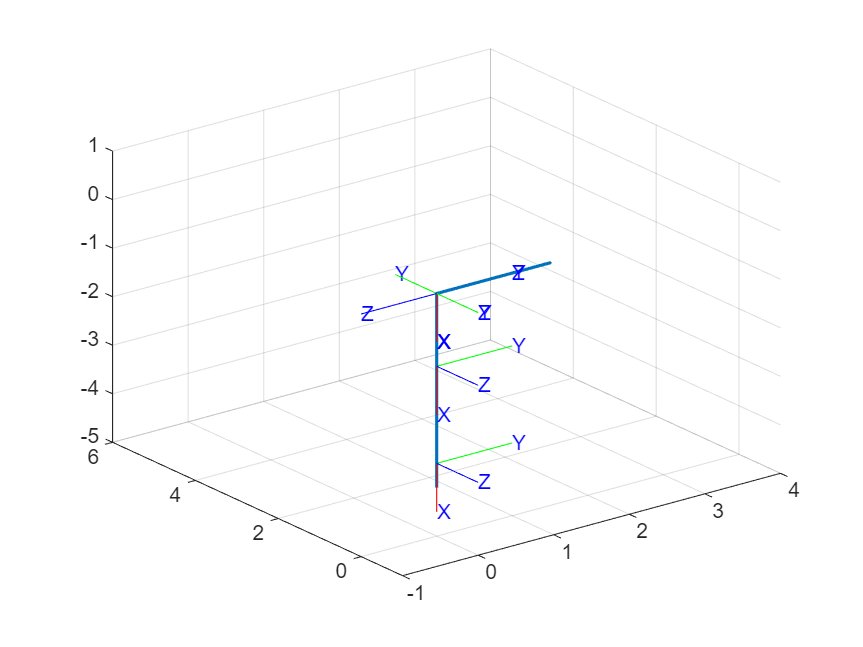


   pause;           
  tranimate(H2_3, H3_4,'rgb','axis', [-1 4 -1 6 -1 2])

  disp(H3_4)

     0         1         0         0
     0         0        -1         0
    -1         0         0      -3.5
     0         0         0         1




  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Variables simbólicas para los ángulos de rotación (pueden ser funciones de t si es necesario)
syms th1(t) th2(t) t l1 l2 l3 l4 real


% Configuración del robot: 0 para rotacional (todas las juntas son rotacionales)
RP = [0 0 0 0];  % Juntas rotacionales

% Vector de coordenadas articulares (ángulos)
Q = [th1; th2];   % Cambié para usar solo th1 y th2
Qp = diff(Q, t);  % Velocidades generalizadas (derivadas)

% Funciones para rotaciones alrededor de X y Y
Rx = @(theta) [1 0 0; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
Ry = @(theta) [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];

% Matrices de transformación homogénea (rotaciones y traslaciones)
H0 = [Ry(pi/2), [0; 0; 0]; 0 0 0 1];    % Rotación sobre Y por pi/2 y traslación [0,0,0]
H1 = [Rx(pi/2), [0; 0; 0]; 0 0 0 1];    % Rotación sobre X por pi/2 y traslación [0,0,0]
H2 = [Rx(pi/2), [0; 0; 0]; 0 0 0 1];    % Rotación sobre X por pi/2 y traslación [0,0,0]
H3 = [Rx(-pi/2), [1.5; 0; 0]; 0 0 0 1]; % Rotación sobre X por -pi/2 y traslación [1.5, 0, 0]
H4 = [Rx(0), [2; 0; 0]; 0 0 0 1];       % Rotación sobre X por 0 y traslación [2, 0, 0]

% Inicializamos las matrices de transformación globales
T(:,:,1) = H0;
T(:,:,2) = H0 * H1;  % T01 = H0 * H1
T(:,:,3) = T(:,:,2) * H2;  % T02 = T01 * H2
T(:,:,4) = T(:,:,3) * H3;  % T03 = T02 * H3
T(:,:,5) = T(:,:,4) * H4;  % T04 = T03 * H4

% Mostrar matrices de transformación globales con disp en lugar de pretty
for i = 1:5
    fprintf('Matriz de Transformación global T%d:\n', i);
    disp(T(:,:,i));
end

Matriz de Transformación global T1:


    0.0000         0    1.0000         0
         0    1.0000         0         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000



Matriz de Transformación global T2:


    0.0000    1.0000    0.0000         0
         0    0.0000   -1.0000         0
   -1.0000    0.0000    0.0000         0
         0         0         0    1.0000



Matriz de Transformación global T3:


    0.0000    0.0000   -1.0000         0
         0   -1.0000   -0.0000         0
   -1.0000    0.0000   -0.0000         0
         0         0         0    1.0000



Matriz de Transformación global T4:


    0.0000    1.0000    0.0000    0.0000
         0    0.0000   -1.0000         0
   -1.0000    0.0000    0.0000   -1.5000
         0         0         0    1.0000



Matriz de Transformación global T5:


    0.0000    1.0000    0.0000    0.0000
         0    0.0000   -1.0000         0
   -1.0000    0.0000    0.0000   -3.5000
         0         0         0    1.0000




% Extracción de posiciones y rotaciones globales
for i = 1:5
    PO(:,i) = T(1:3,4,i);       % Posición global del eslabón i
    RO(:,:,i) = T(1:3,1:3,i);   % Matriz de rotación global del eslabón i
end

% Calculamos el Jacobiano analítico (lineal y angular)
Jv = sym(zeros(3,2));  % Para 2 grados de libertad (ya que solo tenemos th1 y th2)
Jw = sym(zeros(3,2));  % Para 2 grados de libertad (ya que solo tenemos th1 y th2)

for k = 1:2  % Ahora el ciclo recorre solo 2 articulaciones (th1 y th2)
    if RP(k) == 0  % Junta rotacional
        if k == 1
            z_prev = [0; 0; 1];
            p_prev = [0; 0; 0];
        else
            z_prev = RO(:,3,k-1);
            p_prev = PO(:,k-1);
        end
        Jv(:,k) = cross(z_prev, PO(:,2) - p_prev);  % Cambié de 5 a 2 para no exceder el índice
        Jw(:,k) = z_prev;  % Velocidad angular
    else           % Junta prismática (no se usa aquí, pero por si fuera necesario)
        if k == 1
            z_prev = [0; 0; 1];
        else
            z_prev = RO(:,3,k-1);
        end
        Jv(:,k) = z_prev;
        Jw(:,k) = [0; 0; 0];
    end
end

Jv = simplify(Jv);
Jw = simplify(Jw);

% Velocidades lineales y angulares simbólicas
V = simplify(Jv * Qp);  % Velocidad lineal
W = simplify(Jw * Qp);  % Velocidad angular

disp('Jacobiano lineal analítico:');

Jacobiano lineal analítico:


disp(Jv);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

disp('Jacobiano angular analítico:');

Jacobiano angular analítico:


disp(Jw);

$$\left(\begin{array}{cc} 0 & 1\\ 0 & 0\\ 1 & \frac{4967757600021511}{81129638414606681695789005144064} \end{array}\right)$$


disp('Velocidad lineal simbólica V:');

Velocidad lineal simbólica V:


disp(V);

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

disp('Velocidad angular simbólica W:');

Velocidad angular simbólica W:


disp(W);

$$\left(\begin{array}{c} \frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)\\ 0\\ \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)+\frac{4967757600021511\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{81129638414606681695789005144064} \end{array}\right)$$

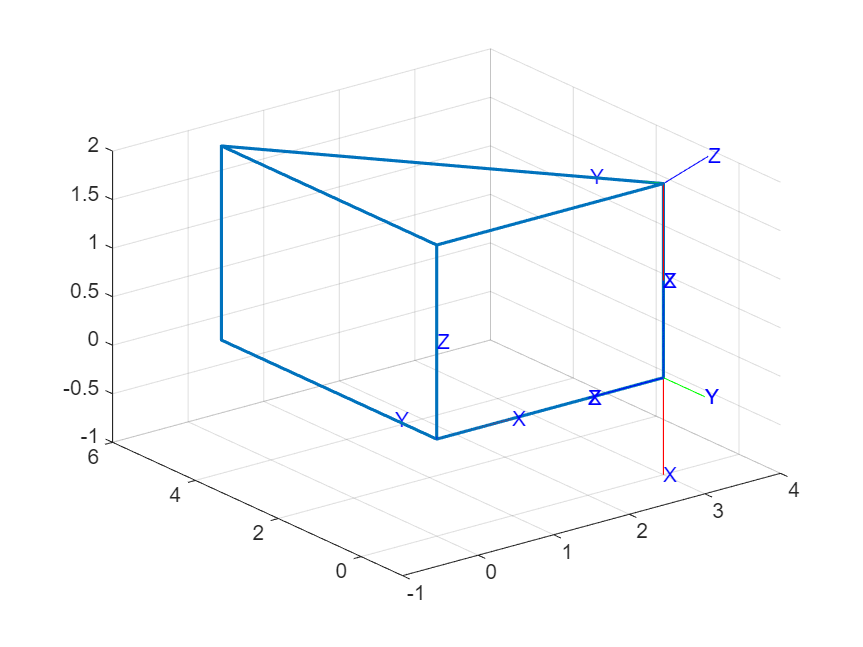

%Limpieza de pantalla
cla
clear
clf

%Calculamos las matrices de transformación homogénea
H0=SE3;                             %Matriz identidad
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0]);

H0_1= H0*H1;
H1_2= H0_1*H2;
H2_3= H1_2*H3; %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H0_1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H0_1, H1_2,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;           
  tranimate(H1_2, H2_3,'rgb','axis', [-1 4 -1 6 -1 2])

  disp(H2_3)

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1


% Definir las matrices de transformación homogénea usando SE3
H0 = SE3; % Matriz identidad
H1 = SE3(rotz(pi), [3 0 0]);                % Rotación sobre Z por pi y traslación [3, 0, 0]
H2 = SE3(roty(pi/2), [0 0 0]);              % Rotación sobre Y por pi/2 y traslación [0, 0, 0]
H3 = SE3(rotx(150*pi/180), [-2 0 0]);       % Rotación sobre X por 150° y traslación [-2, 0, 0]

% Inicializamos la matriz de transformación global final
T = H0 * H1 * H2 * H3;

% Mostrar la matriz de transformación global final
disp('Matriz de Transformación Global Final T:');

Matriz de Transformación Global Final T:


disp(T);

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1



% Variables simbólicas para los ángulos de rotación
syms th1(t) th2(t) th3(t) real


% Configuración del robot (juntas rotacionales)
RP = [0 0 0];  % Juntas rotacionales

% Vector de coordenadas articulares (ángulos de rotación)
Q = [th1; th2; th3];  % Ángulos de rotación
Qp = diff(Q, t);  % Velocidades generalizadas (derivadas de los ángulos)

% Funciones para rotaciones alrededor de X, Y, Z
Rx = @(theta) [1 0 0; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
Ry = @(theta) [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
Rz = @(theta) [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1];

% Matrices de transformación homogénea usando rotaciones y traslaciones simbólicas
H1_sym = [Rz(pi), [3; 0; 0]; 0 0 0 1];
H2_sym = [Ry(pi/2), [0; 0; 0]; 0 0 0 1];
H3_sym = [Rx(150*pi/180), [-2; 0; 0]; 0 0 0 1];

% Inicializamos las matrices de transformación globales simbólicas
T_sym(:,:,1) = H1_sym;
T_sym(:,:,2) = T_sym(:,:,1) * H2_sym;
T_sym(:,:,3) = T_sym(:,:,2) * H3_sym;

% Extraemos las posiciones y rotaciones globales simbólicas
PO_sym(:,1) = T_sym(1:3, 4, 3);  % Posición final
RO_sym(:,:,1) = T_sym(1:3, 1:3, 3);  % Matriz de rotación final

% Calculamos el Jacobiano analítico (lineal y angular)
Jv = sym(zeros(3,3));  % Para 3 grados de libertad
Jw = sym(zeros(3,3));  % Para 3 grados de libertad

for k = 1:2  % Ahora el ciclo recorre las 3 articulaciones (th1, th2, th3)
    if RP(k) == 0  % Junta rotacional
        if k == 1
            z_prev = [0; 0; 1];
            p_prev = [0; 0; 0];
        else
            z_prev = RO_sym(:,3,k-1);
            p_prev = PO_sym(:,k-1);
        end
        Jv(:,k) = cross(z_prev, PO_sym(:,1) - p_prev);  % Velocidad lineal
        Jw(:,k) = z_prev;  % Velocidad angular
    else
        if k == 1
            z_prev = [0; 0; 1];
        else
            z_prev = RO_sym(:,3,k-1);
        end
        Jv(:,k) = z_prev;
        Jw(:,k) = [0; 0; 0];
    end
end

Jv = simplify(Jv);
Jw = simplify(Jw);

% Velocidades lineales y angulares simbólicas
V = simplify(Jv * Qp);  % Velocidad lineal
W = simplify(Jw * Qp);  % Velocidad angular

disp('Jacobiano lineal analítico:');

Jacobiano lineal analítico:


disp(Jv);

$$\left(\begin{array}{ccc} \frac{684969180613545}{45671926166590716193865151022383844364247891968} & 0 & 0\\ 3 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

disp('Jacobiano angular analítico:');

Jacobiano angular analítico:


disp(Jw);

$$\left(\begin{array}{ccc} 0 & \frac{\sqrt{3}}{2} & 0\\ 0 & \frac{1}{2} & 0\\ 1 & -\frac{4302204281461843}{81129638414606681695789005144064} & 0 \end{array}\right)$$


disp('Velocidad lineal simbólica V:');

Velocidad lineal simbólica V:


disp(V);

$$\left(\begin{array}{c} \frac{684969180613545\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}{45671926166590716193865151022383844364247891968}\\ 3\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)\\ 0 \end{array}\right)$$

disp('Velocidad angular simbólica W:');

Velocidad angular simbólica W:


disp(W);

$$\left(\begin{array}{c} \frac{\sqrt{3}\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{2}\\ \frac{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{2}\\ \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)-\frac{4302204281461843\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{81129638414606681695789005144064} \end{array}\right)$$

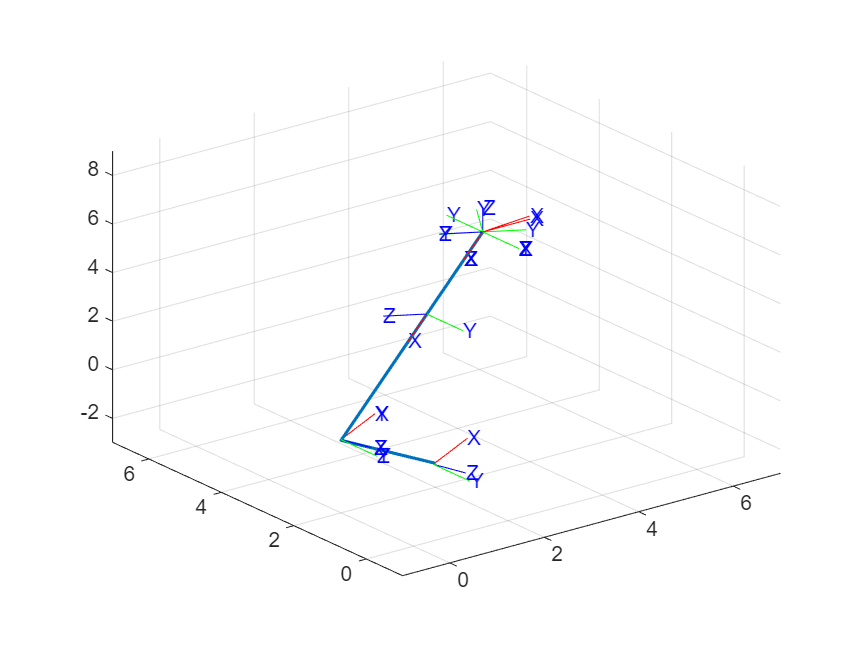

clear
clf
cla

% Definir las matrices de transformación homogénea usando SE3
H0 = SE3([3 2 7]);
H1 = SE3(roty(-pi) * rotz(-pi/2) * rotx(-pi/8), [3 2 7]);
H2 = SE3(rotx(-pi/3) * roty(pi/2), [0 0 0]);
H3 = SE3(rotz(-151/225*pi), [0 0 0]);
H4 = SE3(rotx(pi/2), [0 0 0]);
H5 = SE3([3 0 0]);
rotarz = rotz(-23/180*pi);
H6 = SE3((rotz(pi/2) * roty(pi/2)) * rotarz, [4.588 0 0]);
H7 = SE3(rotz(pi/2) * rotx(pi/2), [0 0 0]);
H8 = SE3([0 0 2.8284]);

% Calculamos las transformaciones sucesivas
H20 = H1 * H2;
H30 = H20 * H3;
H40 = H30 * H4;
H50 = H40 * H5;
H60 = H50 * H6;
H70 = H60 * H7;
H80 = H70 * H8;

% Coordenadas de translación y rotación para graficar
x = [2 0 3];
y = [2 2 2];
z = [-2 0 7];

plot3(x, y, z, 'LineWidth', 1.5);
axis([-1 7 -1 7 -3 9]);
grid on;
hold on;

% Graficamos la trama absoluta o global
trplot(H0, 'rgb', 'axis', [-1 7 -1 7 -3 9]);

% Realizamos una animación para cada transformación
pause;
tranimate(H0, H1, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H1, H20, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H20, H30, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H30, H40, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H40, H50, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H50, H60, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H60, H70, 'rgb', 'axis', [-1 7 -1 7 -3 9]);
pause;
tranimate(H70, H80, 'rgb', 'axis', [-1 7 -1 7 -3 9]);


disp('Matriz de transformación homogénea global T:');

Matriz de transformación homogénea global T:


disp(H80);

     0.723         0    0.6909     1.953
         0        -1         0         2
    0.6909         0    -0.723    -2.014
         0         0         0         1



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Definir el robot con juntas rotacionales
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) real


RP = [0 0 0 0 0 0];  % Juntas rotacionales

% Vector de coordenadas articulares (ángulos de rotación)
Q = [th1; th2; th3; th4; th5; th6];   % Ángulos de rotación
Qp = diff(Q, t);  % Velocidades generalizadas (derivadas de los ángulos)

% Funciones para rotaciones alrededor de X, Y, Z
Rx = @(theta) [1 0 0; 0 cos(theta) -sin(theta); 0 sin(theta) cos(theta)];
Ry = @(theta) [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
Rz = @(theta) [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1];

% Matrices de transformación homogénea usando rotaciones y traslaciones simbólicas
H1_sym = SE3(rotz(-pi) * rotz(-pi/2) * rotx(-pi/8), [3 2 7]);
H2_sym = SE3(rotx(-pi/3) * roty(pi/2), [0 0 0]);
H3_sym = SE3(rotz(-151/225*pi), [0 0 0]);
H4_sym = SE3(rotx(pi/2), [0 0 0]);
H5_sym = SE3([3 0 0]);
rotarz_sym = rotz(-23/180*pi);
H6_sym = SE3((rotz(pi/2) * roty(pi/2)) * rotarz_sym, [4.588 0 0]);
H7_sym = SE3(rotz(pi/2) * rotx(pi/2), [0 0 0]);
H8_sym = SE3([0 0 2.8284]);

% Inicializamos las matrices de transformación globales simbólicas
T_sym(:,:,1) = H1_sym.T;
T_sym(:,:,2) = T_sym(:,:,1) * H2_sym.T;
T_sym(:,:,3) = T_sym(:,:,2) * H3_sym.T;
T_sym(:,:,4) = T_sym(:,:,3) * H4_sym.T;
T_sym(:,:,5) = T_sym(:,:,4) * H5_sym.T;
T_sym(:,:,6) = T_sym(:,:,5) * H6_sym.T;
T_sym(:,:,7) = T_sym(:,:,6) * H7_sym.T;
T_sym(:,:,8) = T_sym(:,:,7) * H8_sym.T;

% Guardar posiciones y rotaciones de cada articulación
for i = 1:8
    T_i = T_sym(:,:,i);           % matriz homogénea 4x4
    PO_sym(:,i) = T_i(1:3, 4);    % columna de posición
    RO_sym(:,:,i) = T_i(1:3, 1:3);% submatriz de rotación
end

% Calculamos el Jacobiano analítico (lineal y angular)
Jv = sym(zeros(3,6));
Jw = sym(zeros(3,6));

for k = 1:6
    if RP(k) == 0  % Rotacional
        if k == 1
            z_prev = [0; 0; 1];
            p_prev = [0; 0; 0];
        else
            z_prev = RO_sym(:,3,k-1);        % eje z anterior
            p_prev = PO_sym(:,k-1);          % posición anterior
        end
        Jv(:,k) = cross(z_prev, PO_sym(:,6) - p_prev);  % usa posición del efector final
        Jw(:,k) = z_prev;
    else  % Prismática (no aplica en este caso)
        if k == 1
            z_prev = [0; 0; 1];
        else
            z_prev = RO_sym(:,3,k-1);
        end
        Jv(:,k) = z_prev;
        Jw(:,k) = [0; 0; 0];
    end
end

% Velocidades simbólicas
V = simplify(Jv * Qp);  % velocidad lineal
W = simplify(Jw * Qp);  % velocidad angular

disp('Jacobiano lineal analítico:');

Jacobiano lineal analítico:


disp(simplify(Jv));

$$\left(\begin{array}{cccccc} -2 & 0 & \frac{1961647284783259}{281474976710656} & \frac{1961647284783259}{281474976710656} & 0 & 0\\ -\frac{6301767377993}{4503599627370496} & -\frac{119283493117523}{1125899906842624} & 0 & 0 & \frac{1897}{250} & \frac{1147}{250}\\ 0 & 0 & \frac{1689637581186185}{562949953421312} & \frac{1689637581186185}{562949953421312} & 0 & 0 \end{array}\right)$$

disp('Jacobiano angular analítico:');

Jacobiano angular analítico:


disp(simplify(Jw));

$$\left(\begin{array}{cccccc} 0 & -\frac{6893811853601123}{18014398509481984} & 0 & 0 & -\frac{1034078695194127}{1125899906842624} & -\frac{1034078695194127}{1125899906842624}\\ 0 & 0 & 1 & 1 & 0 & 0\\ 1 & \frac{4160783518353059}{4503599627370496} & 0 & 0 & -\frac{7125514311802573}{18014398509481984} & -\frac{7125514311802573}{18014398509481984} \end{array}\right)$$


disp('Velocidad lineal simbólica V:');

Velocidad lineal simbólica V:


disp(V);

$$\left(\begin{array}{c} \frac{1961647284783259\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}{281474976710656}-2\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)+\frac{1961647284783259\,\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)}{281474976710656}\\ \frac{1897\,\frac{\partial }{\partial t}{\mathrm{th}}_{5}\left(t\right)}{250}-\frac{119283493117523\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{1125899906842624}-\frac{6301767377993\,\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}{4503599627370496}+\frac{1147\,\frac{\partial }{\partial t}{\mathrm{th}}_{6}\left(t\right)}{250}\\ \frac{1689637581186185\,\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}{562949953421312}+\frac{1689637581186185\,\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)}{562949953421312} \end{array}\right)$$

disp('Velocidad angular simbólica W:');

Velocidad angular simbólica W:


disp(W);

$$\left(\begin{array}{c} -\frac{6893811853601123\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{18014398509481984}-\frac{1034078695194127\,\frac{\partial }{\partial t}{\mathrm{th}}_{5}\left(t\right)}{1125899906842624}-\frac{1034078695194127\,\frac{\partial }{\partial t}{\mathrm{th}}_{6}\left(t\right)}{1125899906842624}\\ \frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)+\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)\\ \frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)+\frac{4160783518353059\,\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}{4503599627370496}-\frac{7125514311802573\,\frac{\partial }{\partial t}{\mathrm{th}}_{5}\left(t\right)}{18014398509481984}-\frac{7125514311802573\,\frac{\partial }{\partial t}{\mathrm{th}}_{6}\left(t\right)}{18014398509481984} \end{array}\right)$$